# Asesoria

### Metodos Numericos

#### 2022-2S : 19/08/2022

clear
syms f(x)

f(x) = sin(x);
df(x) = diff(f, x)

$$df(x) = \cos\left(x\right)$$

eval(df(3))

ans = -0.9900

clear
syms x

f = @(x) sin(x);
df = @(y) subs(diff(f(x), x), y);
df(3)

$$ans = \cos\left(3\right)$$

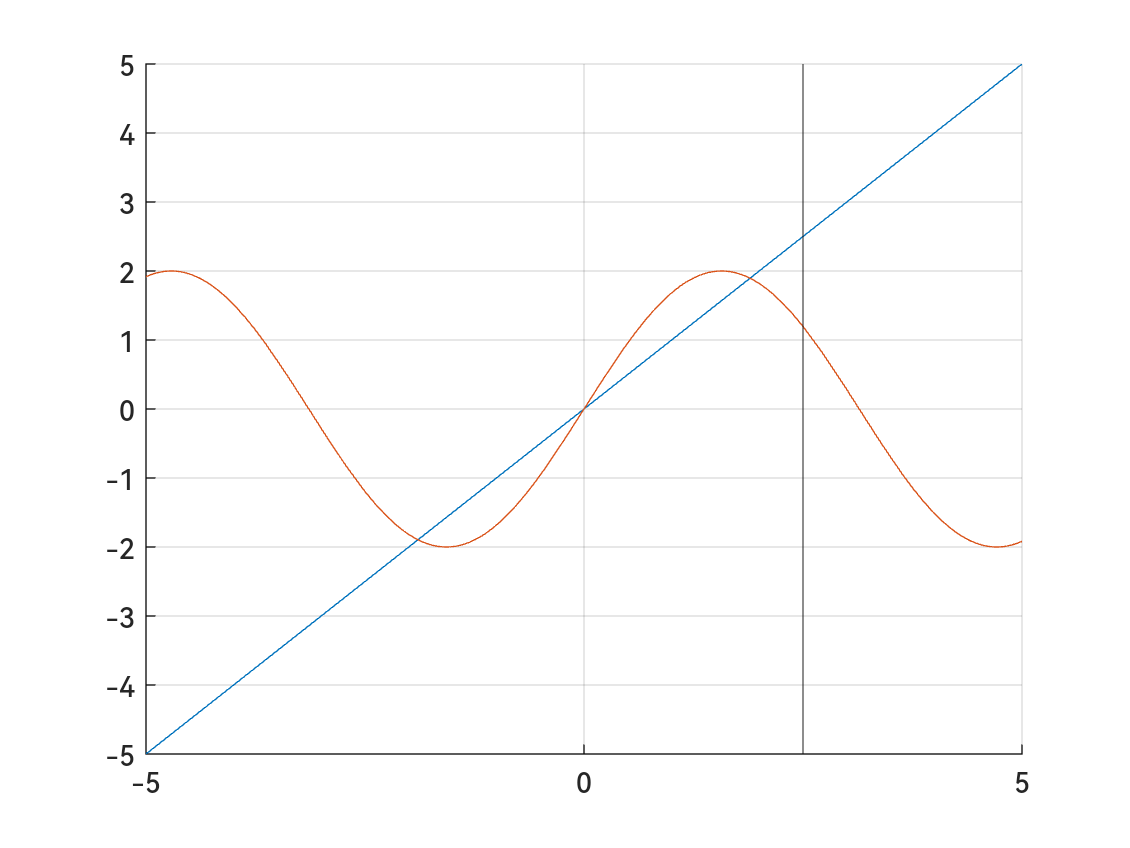

clear

f = @(x) x;
g = @(x) 2* sin(x);

clf('reset')
hold on
fplot(f)
fplot(g)
xline(2.5)
grid on
hold off

help bisect

  Entrada - f es la funcion introducida con @
 	      - a y b son los extremos izquierdo y derecho
 	      - delta es la tolerancia
          - maxIter Maximo de iteración
  Salida  - c es el cero
 	      - yc = f(c)
  	      - err es el error estimado para  c



[~, ~, err] = bisect(@(x) x - 2*sin(x), 1, 2.5, 1e-5, 100)

k = 18

err = -4.3687e-06

help newton

  Entrada - f funcion creada con @
          - df funcion derivada creada con @
          - p0 es la aproximacion inicial a cero de  f
 	      - delta es la tolerancia para  p0
 	      - epsilon es la tolerancia para los valores de la funcion  y
 	      - max1 es el numero maximo de iteraciones
  Salida  - p0 es la aproximacion de Newton-Raphson hacia cero
 	      - err es el error estimado para  p0
 	      - k es el numero de iteraciones
 	      - y es el valor de la funcion  f(p0)



clear
syms f(x)

f(x) = x - 2*sin(x)

$$f(x) = x-2\,\sin\left(x\right)$$

df(x) = diff(f, x)

$$df(x) = 1-2\,\cos\left(x\right)$$

f = matlabFunction(f);
df = matlabFunction(df);

[p, err, k] = newton(f, df, 2.5, 1e-15, 1e-15, 100)

p = 1.8955

err = 1.6580e-10

k = 5

rerr = err / 

rerr = 8.7469e-11